# ThermoeconomicTool demo

Analyze an ORC system, and compare two system configurations:

(1) Produce only electricity working at 30°C condensing temperature (TCND30)

(2) Produce electricity and low-temperature heat for a refrigeration cycle, working at a condensing temperature of 50ºC (TCND50)

**(1) Read data model **

Read the data file and create the model with some parameters. 

model=ThermoeconomicTool('rorc_model.xlsx',...
    'State','TCND50',...
    'CostTables','ALL',...
    'DiagnosisMethod','NONE',...
    'Debug',false);

**(2) Show the results for TCND50**

Set the active waste properties, print the result tables and show ICT and waste allocation graphs

model.setWasteRecycled(model.ActiveWaste,0.6);
model.setWasteType(model.ActiveWaste,'IRREVERSIBILITY');
printResults(model);

Flows Definition Table

  Id Key   From    To      Type      
——————————————————————————————————————
   1 B1    BLR_P1  TRB_F1  INTERNAL  
   2 B2    TRB_F1  IHE_F1  INTERNAL  
   3 B3    IHE_F1  CND_F1  INTERNAL  
   4 B4    CND_F1  PMP_P1  INTERNAL  
   5 B5    PMP_P1  IHE_P1  INTERNAL  
   6 B6    IHE_P1  BLR_P1  INTERNAL  
   7 QBLR  ENV_R1  BLR_F1  RESOURCE  
   8 WP    TRB_P1  PMP_F1  INTERNAL  
   9 WN    TRB_P1  ENV_O1  OUTPUT    
  10 QCND  CND_P1  ENV_W1  WASTE     


Productive Groups Definition Table

  Id Key     Definition  Type      
————————————————————————————————————
   1 BLR_F1  QBLR        FUEL      
   2 BLR_P1  B1-B6       PRODUCT   
   3 TRB_F1  B1-B2       FUEL      
   4 TRB_P1  WN+WP       PRODUCT   
   5 IHE_F1  B2-B3       FUEL      
   6 IHE_P1  B6-B5       PRODUCT   
   7 PMP_F1  WP          FUEL      
   8 PMP_P1  B5-B4       PRODUCT   
   9 CND_F1  B3-B4       FUEL      
  10 CND_P1  QCND        PRODUCT   
  11 ENV_R1  QBLR        RESOURCE  
  12 ENV_O1 

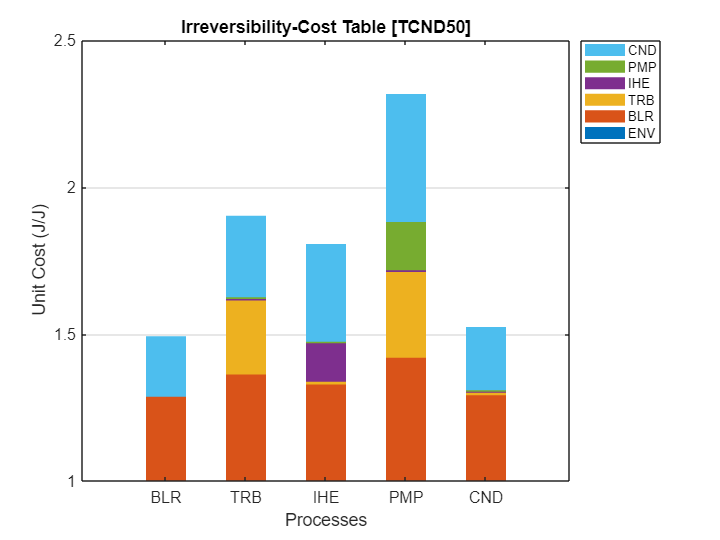

model.showGraph(cType.Tables.PROCESS_ICT);

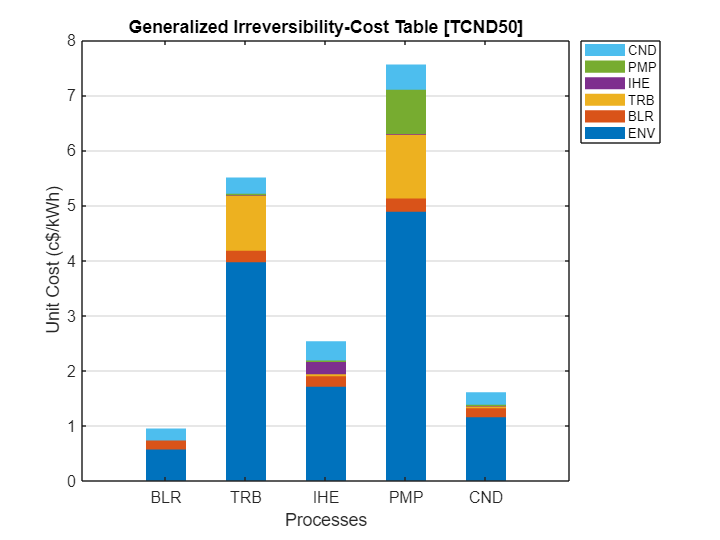

model.showGraph(cType.Tables.PROCESS_GENERAL_ICT)

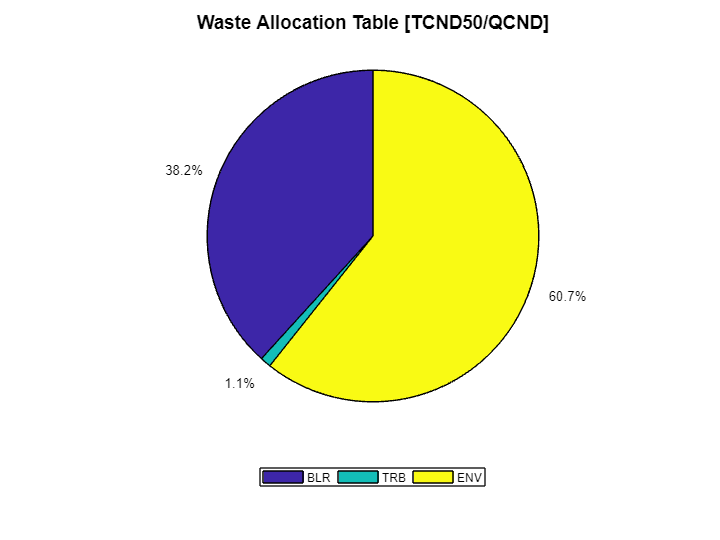

model.showGraph(cType.Tables.WASTE_ALLOCATION);

**(3) Show Summary Results**

Show unit cost summary tables and graph

model.printTable(cType.Tables.SUMMARY_FLOW_UNIT_COST);

Summary Flows Direct Unit Exergy Cost (J/J)

 Key         TCND30     TCND35     TCND50      TRB75     PBLR16      IHE60      noIHE
——————————————————————————————————————————————————————————————————————————————————————
 B1          1.5844     1.6768     1.5238     1.5856     1.6182     1.6128     1.6939
 B2          1.5844     1.6768     1.5238     1.5856     1.6182     1.6128     1.6939
 B3          1.5844     1.6768     1.5238     1.5856     1.6182     1.6128     1.6939
 B4          1.5844     1.6768     1.5238     1.5856     1.6182     1.6128     1.6939
 B5          1.8078     1.9103     1.6744     1.8479     1.8084     1.8398     1.9337
 B6          1.9008     1.9950     1.6982     1.9550     1.9020     1.9750     1.9337
 QBLR        1.0000     1.0000     1.0000     1.0000     1.0000     1.0000     1.0000
 WP          1.9906     2.1065     1.9026     2.1155     2.0341     2.0261     2.1284
 WN          1.9906     2.1065     1.9026     2.1155     2.0341     2.0261     2.1284
 QCND   

model.printTable(cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);

Summary Flows Generalized Unit Cost (c$/kWh)

 Key         TCND30     TCND35     TCND50      TRB75     PBLR16      IHE60      noIHE
——————————————————————————————————————————————————————————————————————————————————————
 B1          1.2511     1.3438     1.1791     1.2616     1.2917     1.2654     1.2655
 B2          1.2511     1.3438     1.1791     1.2616     1.2917     1.2654     1.2655
 B3          1.2511     1.3438     1.1791     1.2616     1.2917     1.2654     1.2655
 B4          1.2511     1.3438     1.1791     1.2616     1.2917     1.2654     1.2655
 B5          2.6245     2.7253     2.3911     2.7285     2.5728     2.6397     2.6387
 B6          2.8042     2.8570     2.4172     2.8856     2.7931     2.9254     2.6387
 QBLR        0.5000     0.5000     0.5000     0.5000     0.5000     0.5000     0.5000
 WP          4.4793     4.8264     5.5055     4.7864     4.8117     4.4971     4.4969
 WN          4.4793     4.8264     5.5055     4.7864     4.8117     4.4971     4.4969
 QCND  

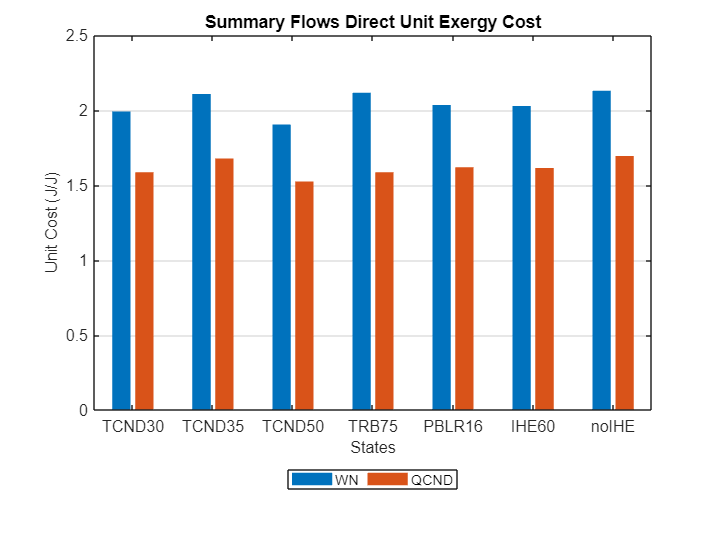

model.showGraph(cType.Tables.SUMMARY_FLOW_UNIT_COST);

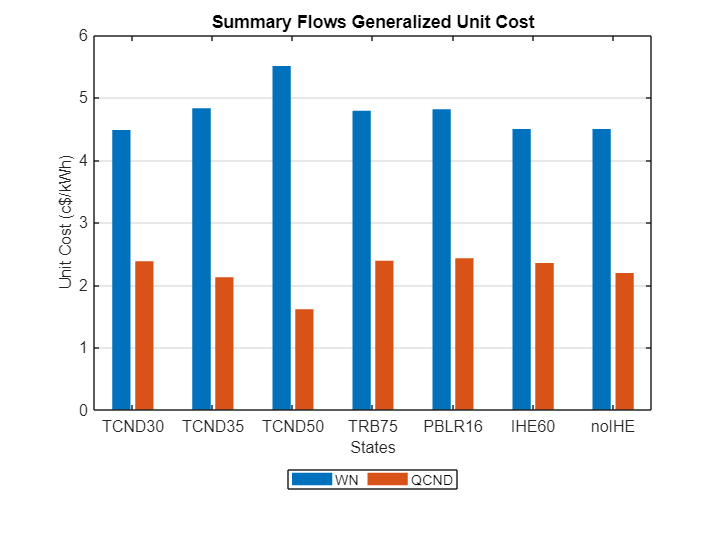

model.showGraph(cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);

**(4) Compare both configurations**

Compare this configuration with the original reference conditions TCND30  using the thermoeconomicDiagnosis function

model.DiagnosisMethod='WASTE_INTERNAL';
model.summaryDiagnosis;

Fuel Impact:    -9.1900 (kW)
Malfunction Cost:    -5.2907 (kW)


model.printTable('dgn');

Diagnosis Summary

Key        MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPs*(kW)
——————————————————————————————————————————————————————————————————————————————
BLR       -4.6938     -5.6960      0.0000     -4.6938      1.3821      0.0000
TRB       -0.5548     -4.0880    -14.5000     -0.5908      0.2020    -27.5879
IHE       -0.3709     -0.2700      0.0000     -0.4810     -0.2392      0.0000
PMP       -0.0236     -0.0370      0.0000     -0.0383      0.0412      0.0000
CND        0.0000      0.4502     14.9508      0.0197      0.0136     22.7826
ENV       -5.6431     -9.6408      0.4508     -5.7843      1.3996     -4.8054



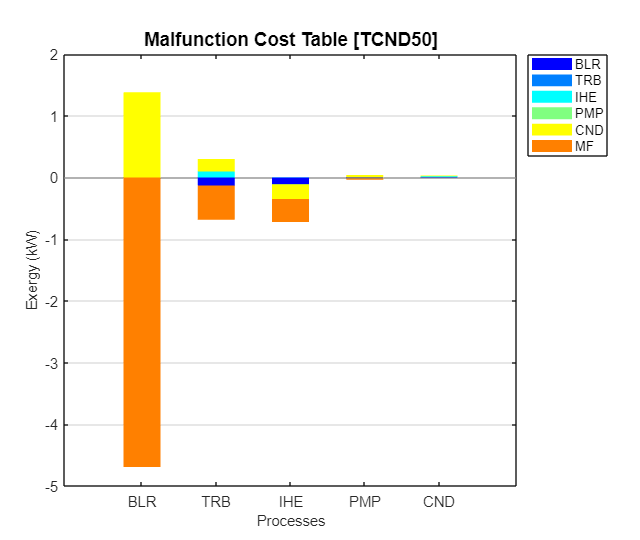

ShowGraph(model,'Graph','mfc','ShowOutput',false);

**(5) Plot the recycling analysis graph**

model.Recycling=true;
res=model.wasteAnalysis;
printResults(res);

Waste Definition Table

Key   Type              Recycling (%)
——————————————————————————————————————
QCND  IRREVERSIBILITY        60.00


Waste Allocation Table  (%)

 Key         QCND
——————————————————
 BLR        37.81
 TRB         1.05
 IHE         0.55
 PMP         0.59
 ENV        60.00


Direct Cost Recycling Analysis (J/J)

 Recycle (%)            WN       QCND
——————————————————————————————————————
      0             2.5471     2.0232
     10             2.4119     1.9184
     20             2.2900     1.8239
     30             2.1795     1.7384
     40             2.0789     1.6604
     50             1.9870     1.5892
     60             1.9026     1.5238
     70             1.8249     1.4636
     80             1.7531     1.4080
     90             1.6866     1.3564
    100             1.6247     1.3085


Generalized Cost Recycling Analysis (c$/kWh)

 Recycle (%)            WN       QCND
——————————————————————————————————————
      0             6.1867     2.1383
     10 

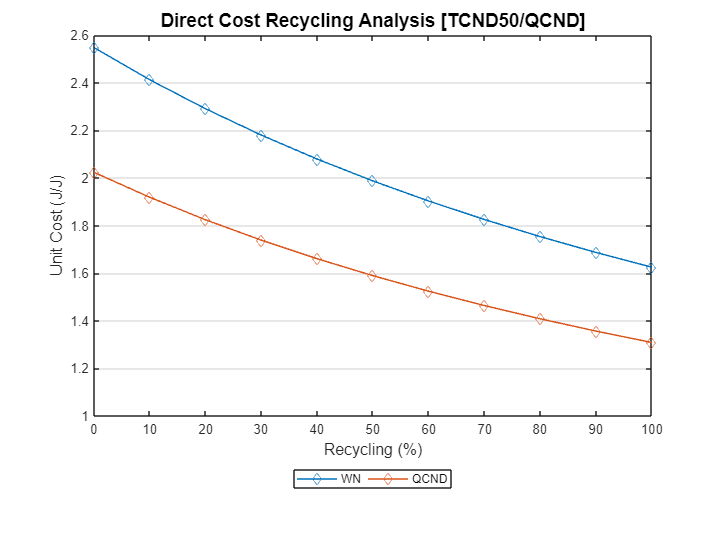

res.showGraph(cType.Tables.WASTE_RECYCLING_DIRECT);

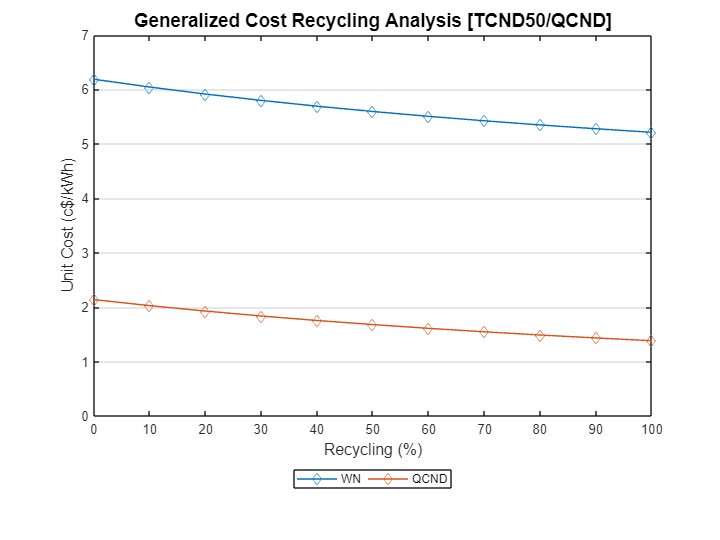

res.showGraph(cType.Tables.WASTE_RECYCLING_GENERAL);